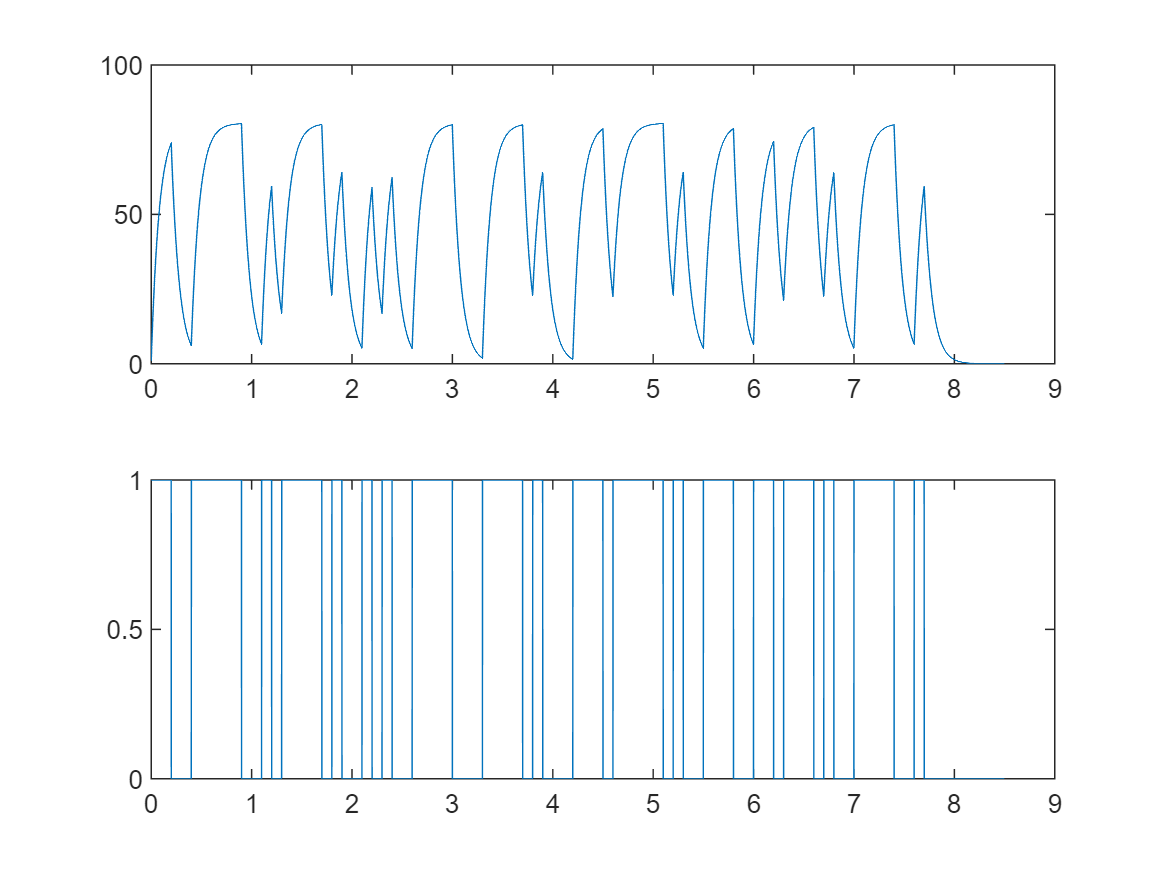

% EGB242 Week 8 template
clear; close all; clc

fs = 1000; % sample rate
Ts = 1 / fs;
Tb = 0.1; % duration of each bit
ptsPerBit = 100; % samples per bit
bitsPerChar = 7; % bits per character

load output.mat

t0 = 0;
samples = length(output);
T = Ts * samples;
t = linspace(t0, t0 + T, samples + 1);
t(end) = [];

impulse = [1/Tb zeros(1, samples-1)]; % All frequencies at once (time domain equivalent)

impulse_resp = System(impulse) * Tb; % Send through system
% Convolution requires enough time for the input signal to completely pass
% through the system, meaning that the output may be longer than the input.
% Depending on your input signal and system, a portion of the output can be 
% removed to maintain the same length. 
impulse_resp = impulse_resp(1:length(output)); % Truncate response to output length
Transfer_func = fft(impulse_resp); % Find frequency domain system response

figure(1), clf, subplot(2,1,1), plot(t, output)
Output = fft(output); % Find frequency domain representation of output

Input = Output ./ Transfer_func; % Deconvolve in frequency domain
input = ifft(Input); % Find time domain equivalent

subplot(2,1,2), plot(t, input)


% Simplify time to bits
input = input(1:end-mod(length(input),ptsPerBit)); % make length multiple of 100
input = reshape(input, ptsPerBit, []); % Reshape to 1 bit duration per column
input = round(mean(input)); % Find bit value for that duration

% Find 7 bit characters
input = input(1:end-mod(length(input),7)); % make length multiple of 7
input = reshape(input, bitsPerChar, []).'; % reshape 7 bits per column, and transpose for 7 bits per row

password = char(bin2dec(num2str(input))).'

password = 'getSchwifty '

%  Decode, and transpose for reading